a = 0.1;

dt = 0.1;
t = -100 : dt : 100;

T = 200;

signal = sin(t) + a*(rand(size(t)) - 0.5);

signal_derivative = cos(t);

signal_numerical_derivative = numerical_derivative(signal, dt);

N = 50;
N_series = -N : 1 : N;

signal_fourier_coeffs = compute_fourier_coeffs(t, signal, T, N);

signal_fourier_derivative = compute_fourier( ...
    t, signal_fourier_coeffs .* ((2 * pi * 1i .* N_series) / T), T ...
);

fourier_derivative_coeffs = compute_fourier_coeffs(t, signal_fourier_derivative, T, N);

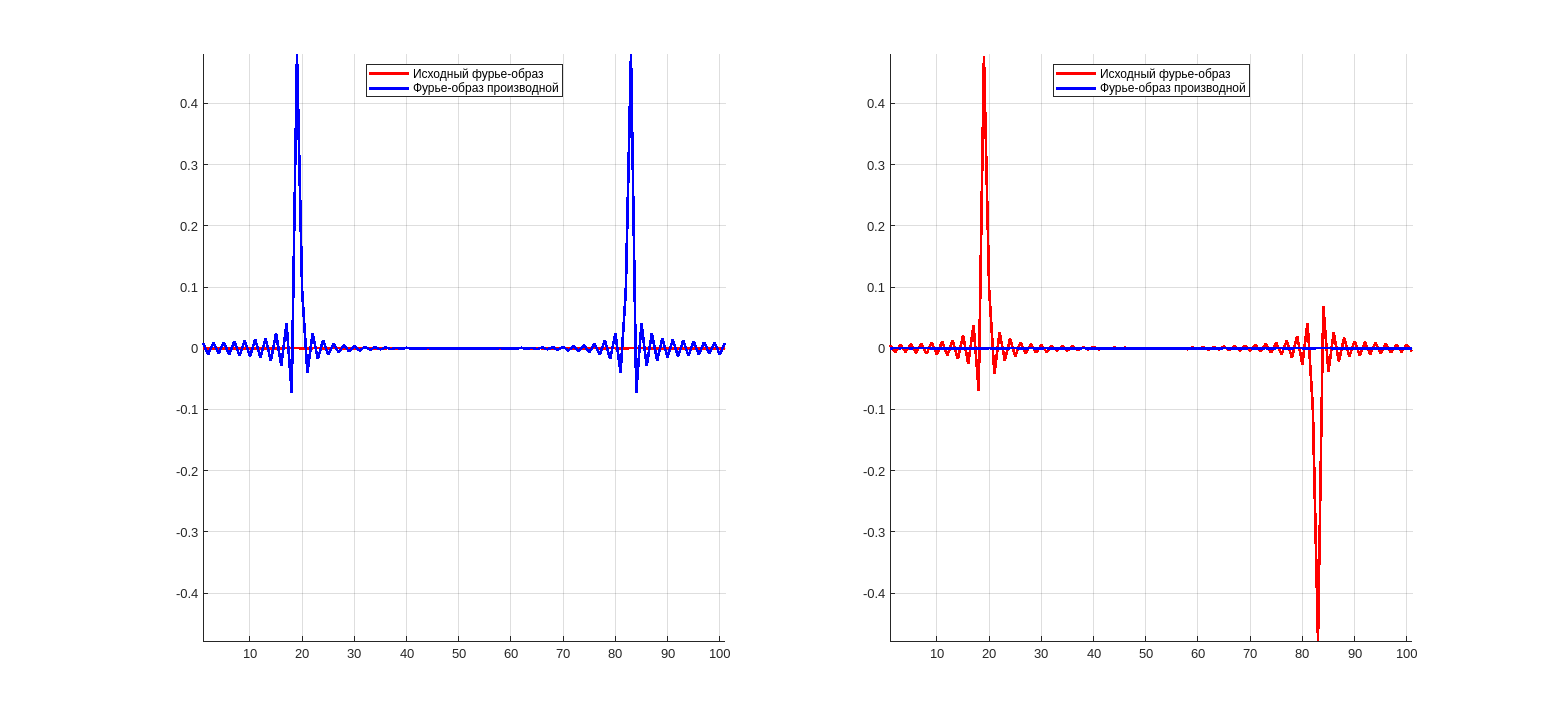

figure;
ax1 = subplot(1, 2, 1);
hold on;
plot(real(signal_fourier_coeffs), 'r', 'LineWidth', 2);
plot(real(fourier_derivative_coeffs), 'b', 'LineWidth', 2);
hold off;
axis(ax1, "tight");
legend(ax1, {'Исходный фурье-образ', 'Фурье-образ производной'}, 'Location', 'north');
grid on;

ax2 = subplot(1, 2, 2);
hold on;
plot(imag(signal_fourier_coeffs), 'r', 'LineWidth', 2);
plot(imag(fourier_derivative_coeffs), 'b', 'LineWidth', 2);
hold off;
legend(ax2, {'Исходный фурье-образ', 'Фурье-образ производной'}, 'Location', 'north');
axis(ax2, "tight");
grid on;

linkaxes([ax1, ax2]);
pos = get(gcf, 'Position');
set(gcf, 'Position', pos + [-1000 -300 1000 300]);

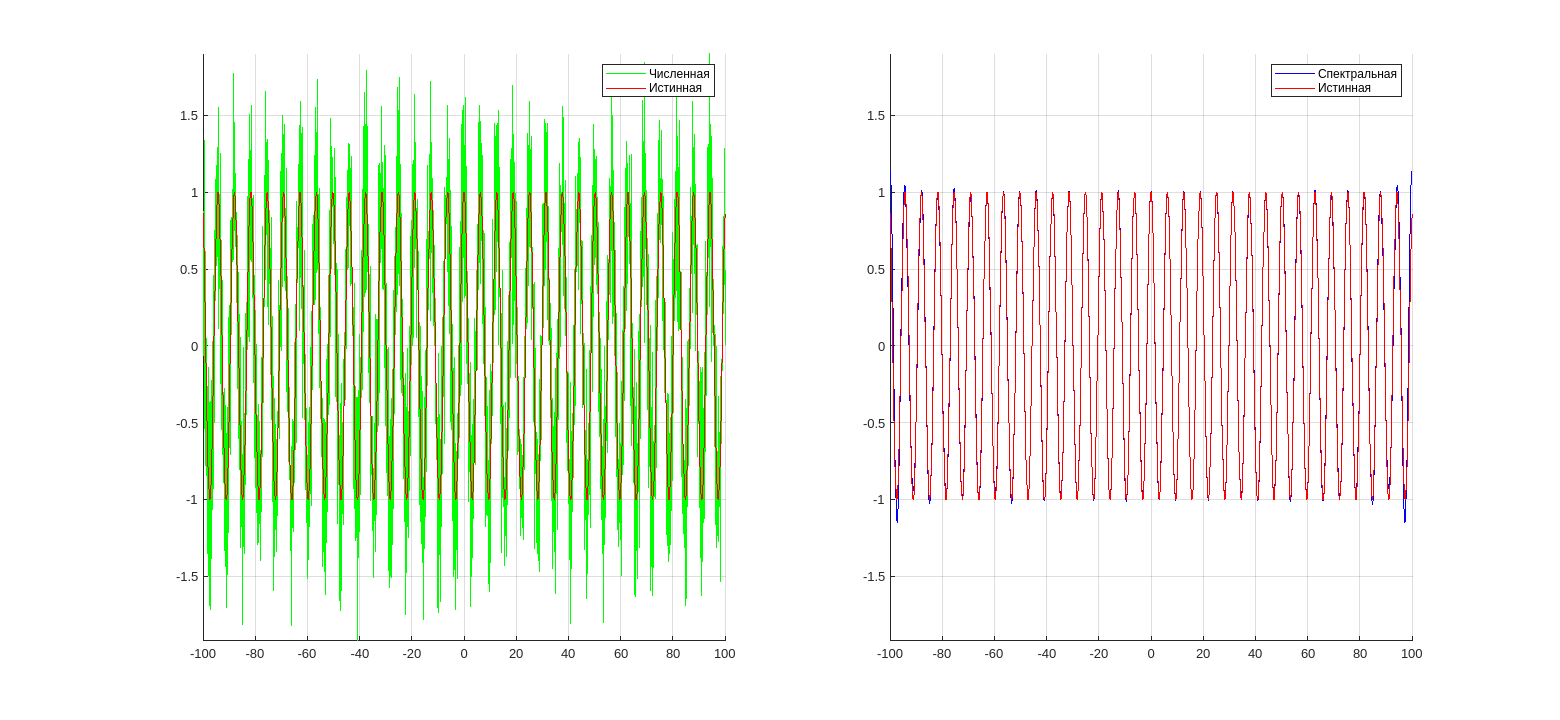

figure;
ax1 = subplot(1, 2, 1);
hold on;
plot(t, signal_numerical_derivative, 'g');
plot(t, signal_derivative, 'r');
hold off;
axis(ax1, 'tight');
legend(ax1, {'Численная', 'Истинная'});
grid on;

ax2 = subplot(1, 2, 2);
hold on;
plot(t, real(signal_fourier_derivative), 'b');
plot(t, signal_derivative, 'r');
hold off;
axis(ax2, 'tight');
legend(ax2, {'Спектральная', 'Истинная'});
grid on;

linkaxes([ax1, ax2]);
pos = get(gcf, 'Position');
set(gcf, 'Position', pos + [-1000 -300 1000 300]);

function derivative = numerical_derivative(vals, interval)
    derivative = zeros(size(vals));

    for i = 1:(length(vals) - 1)
        derivative(i) = (vals(i + 1) - vals(i)) / interval;
    end
end

function fourier_coeffs = compute_fourier_coeffs(x, y, T, N)
    if ~exist('N', 'var')
        N = 25;
    end
 
    w_n = @(n) (2 * pi * n) / T;

    fourier_coeffs = [];
    for n = -N:N
        int_function = y .* exp(-1i * w_n(n) * x);

        real_part = (1 / T) * trapz(x, real(int_function));
        imag_part = (1 / T) * trapz(x, imag(int_function));

        fourier_coeffs = [fourier_coeffs, real_part + 1i*imag_part];
    end
end

function fourier = compute_fourier(x, coeffs, T)
    N = fix(length(coeffs) / 2);
    N = -N : 1 : N;

    w_n = @(n) (2 * pi * n) / T;

    fourier = 0;
    for i = 1:length(N)
        fourier = fourier + coeffs(i) * exp(1i * w_n(N(i)) * x);
    end
end